% --- Template for Quick Plotting of CombinedSpectra from dataTableTrain ---

% --- User Inputs ---
% Choose ONE way to identify the probe:

% Option 1: Specify by Row Index in dataTableTrain
% probe_row_index = 5; % <<< EXAMPLE: Plot spectra for the 5th probe in the table
% probe_identifier_type = 'index'; % Set to 'index' when using probe_row_index

% Option 2: Specify by Diss_ID (Probe/Sample Identifier)
probe_diss_id_to_plot = 'MEN-080-01'; % <<< CHANGE THIS to the actual Diss_ID you want to plot
probe_identifier_type = 'Diss_ID';  % Set to 'Diss_ID' when using probe_diss_id_to_plot

% --- Configuration ---
% Set to true if you want to use the specific ylim from the master prompt, 
% otherwise it will auto-scale the y-axis based on the data.
use_master_prompt_ylim = false; 
master_prompt_ylim = [0 1.0];
master_prompt_yticks = 0:0.2:1.0;

disp('--- Quick Plotting Template Initialized ---');

--- Quick Plotting Template Initialized ---



% --- Ensure necessary data is loaded ---+
if ~exist('dataTableTrain', 'var')
    error(['dataTableTrain not found in workspace. Please load it before running this script. ' ...
           'It should contain at least ''CombinedSpectra'' and an identifier column (e.g., ''Diss_ID'').']);
end
if ~exist('wavenumbers_roi', 'var')
    error(['wavenumbers_roi not found in workspace. Please load it. ' ...
           'This variable should contain the wavenumber values corresponding to your spectra.']);
end

% --- Find the probe and extract spectra ---
rowIndex = [];
identifier_string_for_title = 'Unbekannte Probe'; % Default title string

if strcmpi(probe_identifier_type, 'Diss_ID')
    if ~exist('probe_diss_id_to_plot', 'var') || isempty(probe_diss_id_to_plot)
        error('Variable "probe_diss_id_to_plot" is not set or is empty, but probe_identifier_type is "Diss_ID".');
    end
    if ~ismember('Diss_ID', dataTableTrain.Properties.VariableNames)
        error('dataTableTrain does not have a "Diss_ID" column. Cannot find probe by Diss_ID.');
    end
    
    rowIndex = find(strcmpi(dataTableTrain.Diss_ID, probe_diss_id_to_plot)); % Case-insensitive find
    
    if isempty(rowIndex)
        error('Probe with Diss_ID "%s" not found in dataTableTrain.', probe_diss_id_to_plot);
    elseif length(rowIndex) > 1
        warning('Multiple probes found with Diss_ID "%s". Using the first one found (row %d).', probe_diss_id_to_plot, rowIndex(1));
        rowIndex = rowIndex(1);
    end
    identifier_string_for_title = probe_diss_id_to_plot;
    
elseif strcmpi(probe_identifier_type, 'index')
    if ~exist('probe_row_index', 'var') || isempty(probe_row_index)
        error('Variable "probe_row_index" is not set or is empty, but probe_identifier_type is "index".');
    end
    if probe_row_index > 0 && probe_row_index <= height(dataTableTrain)
        rowIndex = probe_row_index;
        identifier_string_for_title = ['Zeile ' num2str(rowIndex)]; % German: "Row"
        if ismember('Diss_ID', dataTableTrain.Properties.VariableNames) && ...
           iscell(dataTableTrain.Diss_ID) && ~isempty(dataTableTrain.Diss_ID{rowIndex})
            identifier_string_for_title = [identifier_string_for_title ' (Diss_ID: ' dataTableTrain.Diss_ID{rowIndex} ')'];
        end
    else
        error('Invalid probe_row_index: %d. Must be an integer between 1 and %d.', probe_row_index, height(dataTableTrain));
    end
else
    error('Invalid probe_identifier_type: "%s". Choose "Diss_ID" or "index".', probe_identifier_type);
end

% Extract spectra for the selected probe
% Assumes CombinedSpectra{rowIndex} is an N x W matrix (Spectra x Wavenumbers)
if ~ismember('CombinedSpectra', dataTableTrain.Properties.VariableNames)
    error('dataTableTrain does not have a "CombinedSpectra" column.');
end
spectra_to_plot = dataTableTrain.CombinedSpectra{rowIndex};

if isempty(spectra_to_plot)
    disp(['Keine Spektren in CombinedSpectra für Probe gefunden: ' identifier_string_for_title]); % German: No spectra found
    return; % Exit if no spectra
end

if ~isnumeric(spectra_to_plot) || ndims(spectra_to_plot) ~= 2
    error(['CombinedSpectra for probe ' identifier_string_for_title ' is not a 2D numeric matrix.']);
end

if size(spectra_to_plot, 2) ~= length(wavenumbers_roi)
    error(['Anzahl der Wellenzahlen für Probe ' identifier_string_for_title ' stimmt nicht überein. ' ... % German: Mismatch in number of wavenumbers
           'Erwartet: ' num2str(length(wavenumbers_roi)) ', Gefunden: ' num2str(size(spectra_to_plot, 2)) '.'], length(wavenumbers_roi), size(spectra_to_plot, 2));
end

num_spectra_in_sample = size(spectra_to_plot, 1);
disp(['Probe gefunden: ' identifier_string_for_title '. Enthält ' num2str(num_spectra_in_sample) ' Einzelspektren.']); % German: Probe found. Contains X individual spectra.

Probe gefunden: MEN-080-01. Enthält 768 Einzelspektren.


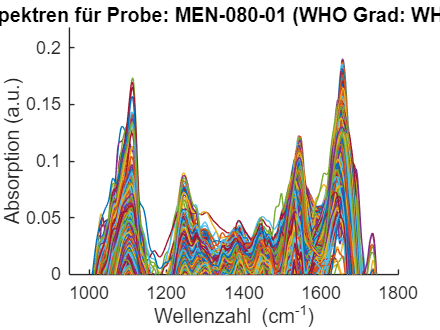


% --- Plotting ---
figure('Name', ['Spektren: ' identifier_string_for_title]); % Figure name
hold on;
for i = 1:num_spectra_in_sample
    plot(wavenumbers_roi, spectra_to_plot(i, :));
end
hold off;

% --- Formatting (Adhering to Master Prompt Guidelines) ---
xlabel('Wellenzahl (cm^{-1})', 'FontSize', 12); % German label
ylabel('Absorption (a.u.)', 'FontSize', 12);    % German label

% Construct title
title_str_prefix = 'Spektren für Probe: '; % German: Spectra for Probe
title_plot = [title_str_prefix identifier_string_for_title];
if ismember('WHO_Grade', dataTableTrain.Properties.VariableNames)
    probe_who_grade = dataTableTrain.WHO_Grade(rowIndex);
    title_plot = [title_plot ' (WHO Grad: ' char(probe_who_grade) ')']; % German: WHO Grade
end
title(title_plot, 'FontSize', 14);

xlim([950 1800]); % As per master prompt

if use_master_prompt_ylim
    ylim(master_prompt_ylim);
    yticks(master_prompt_yticks);
else
    % Optional: slightly adjust auto-scaled y-limits if not using master prompt fixed ones
    curr_ylim = get(gca, 'YLim');
    padding = 0.05 * (curr_ylim(2) - curr_ylim(1));
    if padding == 0; padding = 0.1; end % Handle case where all spectra are flat
    ylim([max(0, curr_ylim(1)-padding) curr_ylim(2)+padding]); % Ensure y_min is not less than 0
end

grid off; % Master prompt specifies grid off
set(gca, 'FontSize', 12);

% ax.XDir = 'reverse'; % Removed, as prompt "higher wavenumbers further down x-axis" means normal direction for xlim [950 1800]

% Add legend if the number of spectra is small enough to be clear
if num_spectra_in_sample == 1
    % No legend needed for a single spectrum
elseif num_spectra_in_sample > 1 && num_spectra_in_sample <= 10 
    legend_str = cell(num_spectra_in_sample, 1);
    for i = 1:num_spectra_in_sample
        legend_str{i} = ['Spektrum ' num2str(i)]; % German: Spectrum
    end
    legend(legend_str, 'Location', 'northeast'); % Changed to northeast for better visibility with common spectral shapes
elseif num_spectra_in_sample > 10
    disp(['Plotting ' num2str(num_spectra_in_sample) ' Spektren. Legende zur Übersichtlichkeit weggelassen.']); % German: Plotting X spectra. Legend omitted for clarity.
end

Plotting 768 Spektren. Legende zur Übersichtlichkeit weggelassen.



disp(['Plot erfolgreich erstellt für: ' identifier_string_for_title]); % German: Plot successfully created

Plot erfolgreich erstellt für: MEN-080-01


disp('--- Quick Plotting Template Finished ---');

--- Quick Plotting Template Finished ---



% --- End of Template ---